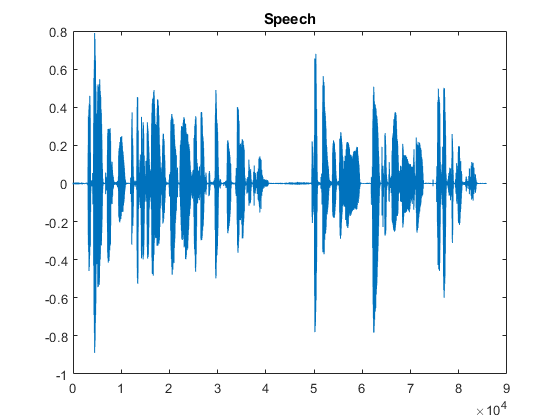

% lab14_ex_speech_compress.m
% Speech compression using linear prediction coding
clear all; close all;
ifigs = 1;             %  0/1 - to show figures inside the processing loop? 

% Parameters
Mlen=240;              % length of analyzed block of samples
Mstep=180;             % offset between analyzed data blocks (in samples)
Np=2;                  % prediction order (IIR-AR filter order)
where=181;             % initial position of the first voiced excitation
roffset=20;            % offset in auto-correlation function when find max
compress=[];           % table for calculated speech model coefficients
s=[];                  % the whole synthesized speech
ss=[];                 % one fragment of synthesized speech

% Read signal to compress
[x,fs]=audioread('mowa1.wav');	   % read speech signal (audio/wav/read)
figure; plot(x); title('Speech');  % display it

% soundsc(x,fs); pause               % play it on loudspeakers (headphones)
N=length(x);                       % signal length
bs=zeros(1,Np);			   % synthesis filter buffer
Nblocks=floor((N-Mlen)/Mstep+1);   % number of speech blocks to be analyzed


T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 67

T = 0

T = 0

T = 40

T = 41

T = 41

T = 44

T = 0

T = 0

T = 32

T = 30

T = 28

T = 27

T = 26

T = 25

T = 24

T = 24

T = 25

T = 25

T = 26

T = 27

T = 0

T = 0

T = 0

T = 21

T = 45

T = 48

T = 51

T = 52

T = 52

T = 47

T = 50

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 45

T = 44

T = 41

T = 37

T = 33

T = 29

T = 27

T = 27

T = 27

T = 0

T = 42

T = 0

T = 74

T = 0

T = 0

T = 39

T = 40

T = 42

T = 0

T = 0

T = 0

T = 42

T = 44

T = 49

T = 0

T = 0

T = 44

T = 47

T = 47

T = 48

T = 53

T = 67

T = 0

T = 47

T = 48

T = 50

T = 50

T = 44

T = 39

T = 36

T = 33

T = 31

T = 30

T = 29

T = 30

T = 31

T = 33

T = 35

T = 37

T = 38

T = 38

T = 38

T = 39

T = 40

T = 41

T = 0

T = 0

T = 0

T = 0

T = 0

T = 39

T = 40

T = 40

T = 41

T = 41

T = 42

T = 44

T = 20

T = 20

T = 43

T = 0

T = 44

T = 42

T = 43

T = 43

T = 45

T = 47

T = 47

T = 48

T = 49

T = 49

T = 49

T = 49

T = 50

T = 50

T = 0

T = 0

T = 33

T = 30

T = 28

T = 27

T = 0

T = 0

T = 0

T = 24

T = 24

T = 24

T = 25

T = 26

T = 28

T = 0

T = 0

T = 0

T = 0

T = 0

T = 38

T = 0

T = 0

T = 0

T = 0

T = 0

T = 43

T = 45

T = 47

T = 48

T = 50

T = 51

T = 0

T = 0

T = 0

T = 71

T = 0

T = 0

T = 0

T = 0

T = 47

T = 49

T = 50

T = 52

T = 57

T = 0

T = 55

T = 54

T = 0

T = 0

T = 0

T = 0

T = 40

T = 42

T = 44

T = 45

T = 46

T = 48

T = 49

T = 49

T = 49

T = 0

T = 0

T = 0

T = 0

T = 52

T = 53

T = 52

T = 0

T = 58

T = 0

T = 0

T = 0

T = 0

T = 39

T = 0

T = 44

T = 55

T = 60

T = 0

T = 65

T = 43

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 72

T = 76

T = 0

T = 42

T = 57

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 49

T = 54

T = 0

T = 62

T = 0

T = 0

T = 0

T = 0

T = 54

T = 0

T = 45

T = 0

T = 0

T = 0

T = 49

T = 47

T = 47

T = 48

T = 53

T = 51

T = 51

T = 47

T = 45

T = 0

T = 47

T = 0

T = 47

T = 45

T = 46

T = 48

T = 47

T = 46

T = 45

T = 47

T = 0

T = 43

T = 0

T = 0

T = 0

T = 39

T = 40

T = 0

T = 32

T = 30

T = 29

T = 30

T = 0

T = 0

T = 0

T = 44

T = 45

T = 38

T = 42

T = 46

T = 48

T = 50

T = 52

T = 51

T = 52

T = 52

T = 79

T = 0

T = 43

T = 51

T = 51

T = 49

T = 51

T = 56

T = 0

T = 0

T = 0

T = 50

T = 51

T = 52

T = 55

T = 55

T = 0

T = 48

T = 52

T = 50

T = 52

T = 52

T = 52

T = 52

T = 51

T = 51

T = 50

T = 50

T = 49

T = 46

T = 42

T = 36

T = 32

T = 29

T = 29

T = 0

T = 42

T = 42

T = 0

T = 0

T = 0

T = 0

T = 0

T = 72

T = 72

T = 69

T = 78

T = 0

T = 35

T = 42

T = 44

T = 46

T = 48

T = 49

T = 50

T = 50

T = 51

T = 53

T = 51

T = 0

T = 0

T = 0

T = 0

T = 48

T = 50

T = 56

T = 54

T = 0

T = 0

T = 0

T = 73

T = 43

T = 42

T = 41

T = 39

T = 38

T = 36

T = 36

T = 37

T = 0

T = 0

T = 0

T = 0

T = 45

T = 48

T = 51

T = 52

T = 53

T = 54

T = 55

T = 56

T = 55

T = 52

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 48

T = 49

T = 48

T = 45

T = 42

T = 38

T = 36

T = 33

T = 32

T = 0

T = 43

T = 0

T = 0

T = 68

T = 75

T = 65

T = 78

T = 70

T = 0

T = 0

T = 0

T = 0

T = 0

T = 0

T = 41

T = 44

T = 46

T = 48

T = 53

T = 0

T = 38

T = 45

T = 44

T = 44

T = 43

T = 0

T = 0

T = 0

T = 0

T = 25

T = 0

T = 28

T = 28

T = 30

T = 0

T = 0

T = 0

T = 0

T = 48

T = 52

T = 63

T = 68

T = 52

T = 0

T = 0

T = 0

T = 0

T = 21

T = 0

T = 0

T = 20

T = 0

T = 0

T = 0

T = 51

T = 45

T = 0

T = 0

T = 40

T = 41

T = 0

T = 0

T = 0

T = 71

T = 0

T = 0

T = 0

T = 61

T = 71

T = 71

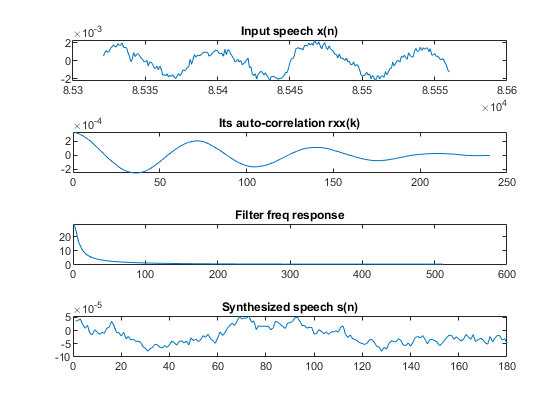

% MAIN PROCESSING LOOP
for  nr = 1 : Nblocks
   % take new data block (fragment of speech samples)
     n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
     bx = x(n);
   % ANALYSIS - calculate speech model parameters
	 bx = bx - mean(bx);                             % remove mean value
     for k = 0 : Mlen-1
         r(k+1)=sum( bx(1:Mlen-k) .* bx(1+k:Mlen) ); % calculate auto-correlation
     end                                             % try: r=xcorr(x,'unbiased')
     if(ifigs==1)
       subplot(411); plot(n,bx); title('Input speech x(n)');
       subplot(412); plot(r); title('Its auto-correlation rxx(k)');
     end
     [rmax,imax] = max( r(roffset : Mlen)  );        % find max of auto-correlation
     imax = imax+(roffset-1);                        % its argument (position)
     if ( rmax > 0.35*r(1) )  T=imax; else T=0; end  % is the speech periodic?
     if (T>80) T=round(T/2); end                     % second sub-harmonic found
     T, % pause                                      % display speech period T
     rr(1:Np,1)=(r(2:Np+1))';                    % create an auto-correlation vector 
     for m=1:Np                                  %
         R(m,1:Np)=[r(m:-1:2) r(1:Np-(m-1))];	 % build an auto-correlation matrix
     end                                         % a = lpc(x,Np), levinson(x,Np)
     a=-inv(R)*rr;                               % find coeffs of LPC filter
     gain=r(1)+r(2:Np+1)*a;                      % find filter gain
     H=freqz(1,[1;a]);                           % find filter frequency response
     if(ifigs==1) subplot(413); plot(abs(H)); title('Filter freq response'); end
   % compress=[compress; T; gain; a; ];          % store parameter values

   % SYNTHESIS - generate speech using calculated parameters
     T = 0; % remove "%" and set: T = 80, 50, 30, 0
     if (T~=0) where=where-Mstep; end            % next excitation=1 position
     for n=1:Mstep                               % SYNTHESIS LOOP START
         if( T==0)                               %
           % exc=2*(rand(1,1)-0.5); where=271;   % random excitation
             exc=0.5*randn(1,1); where=271;      % random excitation
         else                                    %
            if (n==where) exc=1; where=where+T;  % excitation = 1
            else exc=0; end                      % excitation = 0
         end                                     %
         ss(n) = gain*exc - bs*a;                % filtering excitation
         bs = [ss(n) bs(1:Np-1) ];               % shifting the output buffer
     end                                         % SYNTHESIS LOOP END
     s = [s ss];                                 % store the synthesized speech
     if(ifigs==1) subplot(414); plot(ss); title('Synthesized speech s(n)'); end
end

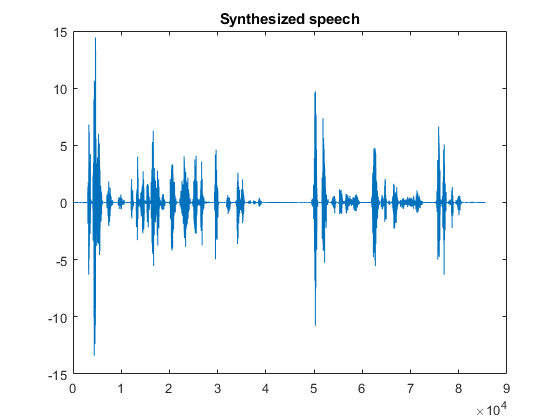


% Finished!
figure; plot(s); title('Synthesized speech');

% soundsc(s,fs)
